# Identificación de Sistemas. Caso de uso: Filtros pasa bajas activos

### Modelado del sistema

Por simplicidad, considere la configuración de amplificador inversor con impedancias para un modelo ideal:

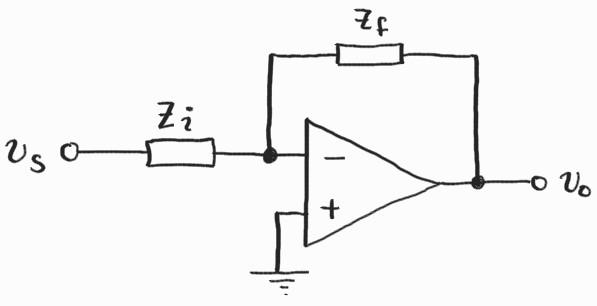

*Figura 1. Amplificador inversor*

la función de transferencia resultante es


$$\frac{v_o}{v_s}=-\frac{Z_{f}}{Z_{i}}$$


Para un filtro pasa bajas activo de orden 1, la impedancia de retroalimentación está dada por la respuesta en paralelo de la resistencia de retroalimentación y el capacitor de retroalimentación.

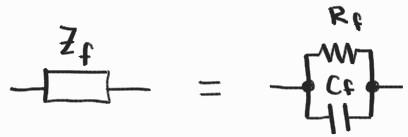

*Figura 2. Impedancia de retroalimentación*

Por tanto,


$$Z_{f}=R_{f}||C_{f}$$


Para simplificar el proceso de modelado se hace uso de la transformada de Laplace,


$$\mathcal{L}[Z_{f}] = \frac{R_{f}}{R_{f}C_{f}\mathcal{s} + 1}$$


En la impedancia de entrada consideramos solo una resistencia $R_{i}$


$$Z_{i}=R_{i}$$


La función de transferencia queda como,


$$G(s)=-\frac{R_{f}}{R_{i}}\frac{1}{R_{f}C_{f}\mathcal{s}+1}$$


### Simulando comportamiento del modelo

Ajuste los valores para $R_{i}=6.8k\Omega@1\%$, $R_{f}=12k\Omega@1\%$ y $C_{f}=10nF@10\%$

Ri =6842;
Rf =11950;
Cf =1.08e-8;

model = tf(-Rf/Ri,[Rf*Cf, 1])

model =
 
      -1.747
  ---------------
  0.0001291 s + 1
 
Continuous-time transfer function.



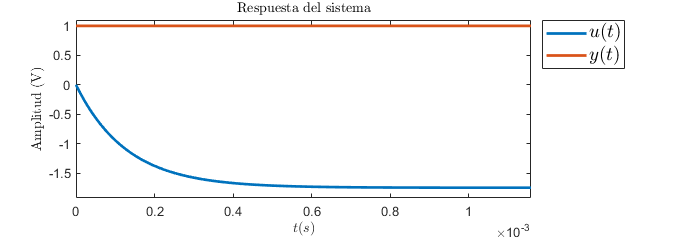

[y, t] = step(model);
figure('Renderer', 'painters', 'Position', [0 0 680 240])
plot([t t], [y ones(size(t))], 'LineWidth', 2)
axis([t(1) t(end) 1.1*[min(y) 1]])
xlabel('$t (s)$',"Interpreter","latex")
ylabel('Amplitud (V)', "Interpreter","latex")
legend({'$u(t)$' '$y(t)$'}, "FontSize", 14, 'Interpreter',"latex",...
    "Location","bestoutside")
title('Respuesta del sistema', "Interpreter","latex")

Anidando dos etapas de filtrado obtenemos un sistema de segundo orden. Si los parámetros son iguales en ambos filtros la función de transferencia obtenida es la siguiente:


$$G(s)=\left(\frac{R_{f}}{R_{i}}\right)^{2}\frac{1}{\left(R_{f}C_{f}\right)^{2}s^{2}+2R_{f}C_{f}+1}$$
 

ndOrder = model*model

ndOrder =
 
               3.05
  -------------------------------
  1.666e-08 s^2 + 0.0002581 s + 1
 
Continuous-time transfer function.



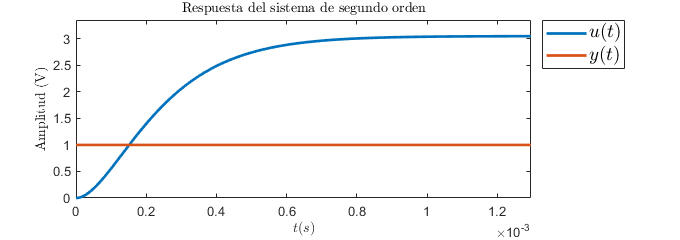

[y, t] = step(ndOrder);
figure('Renderer', 'painters', 'Position', [0 0 680 240])
plot([t t], [y ones(size(t))], 'LineWidth', 2)
axis([t(1) t(end) 0 1.1*max(y)])
legend({'$u(t)$' '$y(t)$'}, "FontSize", 14, 'Interpreter',"latex",...
    "Location","bestoutside")
xlabel('$t (s)$',"Interpreter","latex")
ylabel('Amplitud (V)', "Interpreter","latex")
title('Respuesta del sistema de segundo orden', "Interpreter","latex")

### Estimación de la función de transferencia

Se cargan los datos obtenidos del sistema de medición (DAQ). *Waveforms* entrega un archivo **.csv** con un encabezado que muestra la información de la adquicisión, esto es comparable con el archivo generado por un oscilloscopio digital. Debido a esto, es necesario agregar un offset a la lectura de **24** registros.

% Tres variables a importar
opts = delimitedTextImportOptions("NumVariables", 3);
% Lectura de todos los registros apartir de la linea 24
% con ',' como delimitador de separación
opts.DataLines = [24, Inf];
opts.Delimiter = ",";
% Nombre de las variables y tipo de dato capturado
opts.VariableNames = ["kTs", "uk", "yk"];
opts.VariableTypes = ["double", "double", "double"];
% Ignorar demás columnas e intrtpretar datos vacios
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
tbl = readtable("Samples\Filter0002.csv", opts);
[kTs, uk, yk] = deal(tbl.kTs, tbl.uk, tbl.yk);
clear opts tbl

Visualización de los datos adquirirdos

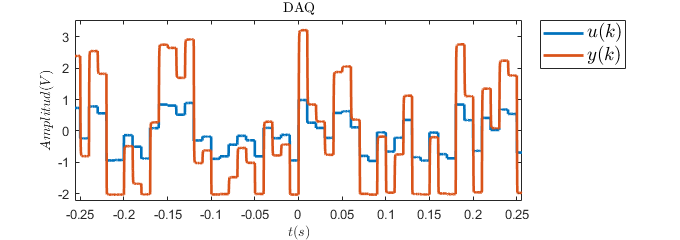

figure('Renderer', 'painters', 'Position', [0 0 680 240])
plot([kTs kTs], [uk yk], "LineWidth", 2)
axis([kTs(1) kTs(end) 1.1*[min(yk) max(yk)]])
title('DAQ', 'Interpreter',"latex")
xlabel('$t (s)$',"Interpreter","latex")
ylabel('$Amplitud (V)$', "Interpreter","latex")
legend({'$u(k)$' '$y(k)$'}, "Interpreter", "latex", 'Location',"bestoutside",...
    "FontSize", 14)

Se propone un orden para la función de transferencia a estimar

n =2;
Ts = abs(kTs(1) - kTs(2));
Phi = GeneratePhi(uk, yk, n);
[zTF, Theta] = DiscreteModel(Phi, yk, Ts);
cTF = d2c(zTF, 'zoh')
 

### Visualización del comportamiento

Observación de la respuestas del sistema ante estimulos variados

f=1801;
t = linspace(0, 2/f, length(kTs))';
stimulus = uk;
yms = lsim(ndOrder, stimulus, t);
yes = lsim(cTF, stimulus, t);
figure('Renderer', 'painters', 'Position', [0 0 680 240])
plot([t t t], [stimulus yms yes], "LineWidth", 2)
axis([t(1) t(end) 1.1*[min(min([stimulus yms yes])) max(max([stimulus yms yes]))]])
title('Respuesta del filtro a estimulos', "Interpreter","latex")
xlabel('$t (s)$',"Interpreter","latex")
ylabel('$Amplitud (V)$', "Interpreter","latex")
legend({'$u(t)$' '$y(t)$' '$\hat{y}(y)$'}, "Interpreter","latex",...
    'Location',"bestoutside", "FontSize", 14)
 

### Conclusión

La diferencia entre el modelo analítico y el experimental se debe a la suposición extrema de simplicidad en el comportamiento del circuito. Al usar el *amplificador ideal* se considera que la impedancia interna de entrada es $\infty$ y la impedancia interna de salida es $0$; usar la ganancia en lazo abierto $a$ solo da como respuesta una función de transferencia escalada que describe el mismo comportamiento. No usar el modelo ideal incrementaría la complejidad de las ecuaciones a analizar. Por otro lado, el modelo ideal proporciona solo una aproximación del comportamiento del sistema para la validación entre el modelo y el experimento, y así determinar si es necesario considerar más parámetros.

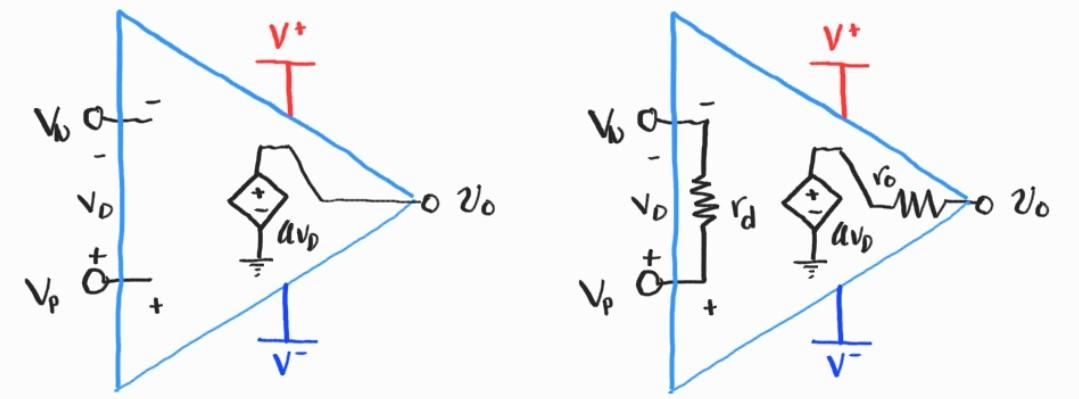

*Figura 3. Modelos del amplificador operacional. Izquierda: modelo ideal. Derecha: primera aproximación con impedancias internas*

### A. Funciones implementadas

Función para generar la matriz $\Phi$

function [Phi] = GeneratePhi(u, y, order)
    NSamples = length(u);
    Phi = zeros(NSamples - order, 2*order);
    for r = 1: NSamples - order
        f = zeros(1, 2*order);
        for c = 1: order
            f(c) = y(r + order - c);
            f(order + c) = u(r + order - c);
        end
        Phi(r, :) = f;
    end
end

Función para generar la función de transferencia discreta $\mathcal{Z}$ y sus parámetros

function [zTF, Theta] = DiscreteModel(Phi, y, Ts)
    n = size(Phi, 2)/2;
    Theta = (Phi'*Phi)\Phi'*y(n + 1: end);
    zTF = tf(Theta(n + 1: end)', [1 -Theta(1:n)'], Ts);
end